## Lösung mittels äquidistanter Diskretisierung 


$$\textrm{Schrittweite}\;\;\Delta x=\frac{1}{N}$$


###  
$${\textrm{zweite}\;\textrm{Differenz}:\;u}_i \approx \;\frac{\left(u_{i-1} -2u_i +u_{i+1} \right)}{h^2 }$$
  

### 
$$\;\textrm{zu}\;\textrm{loesen}:\delta_t U\left(t\right)=-A_1 U\left(t\right)+b\left(t\right)$$


### 
$$\textrm{Implizit}\;\textrm{Euler}:\left(I+k\;\;\Delta t\;A\right)U^{k+1} =\;+\Delta {t\;b}^{k+1}$$


clear all;
clc;


## analytische Loesung

f_analytisch = @(x,t) sin(pi*x)*exp(-1*pi^2*t);
U0 = @(x) sin(x*pi);

N =50;
x = linspace(0,1,N+1);
t = 0:0.01:0.5;

u_analytisch = zeros(size(x,2),size(t,2));

for i= 1:size(x,2)
    for j =1:size(t,2)
        u_analytisch(i,j) = f_analytisch(x(i),t(j));
    end
end

surf(u_analytisch);
colormap default;
xticks([0 size(t,2)/2 size(t,2)]);
xticklabels([0. 0.25 0.5])
xlabel("time");
yticks([0 size(x,2)/2 size(x,2)]);
yticklabels([0. 0.5 1])
ylabel("positon");

view([34.685 19.642]);



## Aufgabe a:

implizit Euler:

## 
$$\textrm{Implizit}\;\textrm{Euler}:\frac{\delta_{k+1} U\left(t\right)-\delta_{k-1} U\left(t\right)}{\delta t}=-\textrm{AU}\left(t\right)$$


clear all;
% anzahl an punken in x Richtung
N =50;
u0 = linspace(0,1,N+1);

%startwerte zuweisen in u0
for i=1:N+1
    u0(i) = sin(pi*u0(i));
end

%diskretisierung in zeitrichtung
tspan = 0:0.01:0.5;

%u(t,x) erstellen
u_euler = zeros(size(tspan,1), (N-1));

% A matrix  und b Vekor erstellen
[A, b] = laplace(N-1,1);

% startwerte zuweisen
u_euler(1,:) = u0(2:N);

%% solve  mit impl. Euler
dt = tspan(2)- tspan(1);

for i=1:size(tspan,2)
    u_euler(i+1,:) = (dt*A-eye((N-1)^1))^(-1)*(-u_euler(i,:)'-dt*b);
end

u_euler = u_euler.';

%randwerte zum plot hinzufuegen
for i=1:size(tspan,2)
    u_euler(1,i) = u0(1);
    u_euler(size(u_euler,2)-1,i) = u0(size(u0,1));
end

%u_euler = HeatImpEuler(u0, tspan);

% plot
surf(u_euler);
xticks([0 size(tspan,2)/2 size(tspan,2)]);
xticklabels([0. 0.25 0.5])
xlabel("time");
yticks([0 size(u0,2)/2 size(u0,2)]);
yticklabels([0. 0.5 1])
ylabel("positon");

view([34.685 19.642]);


## Aufgabe 4 a Trapezregel

clear all;
% anzahl an punken in x Richtung
N =50;
u0 = linspace(0,1,N+1);

%startwerte zuweisen in u0
for i=1:N+1
    u0(i) = sin(pi*u0(i));
end

%diskretisierung in zeitrichtung
tspan = 0:0.01:0.5;

%u(t,x) erstellen
u_trapez = zeros(size(tspan,1), (N-1));

% A matrix  und b Vekor erstellen
[A, b] = laplace(N-1,1);

% startwerte zuweisen
u_trapez(1,:) = u0(2:N);

%% solve  mit trapez regel
dt = tspan(2)- tspan(1);

for i=1:size(tspan,2)
    u_trapez(i+1,:) = (dt*A-eye((N-1)))^(-1)*(-u_trapez(i,:)'-dt*b);
end

u_trapez = u_trapez.';

%randwerte zum plot hinzufuegen
for i=1:size(tspan,2)
    u_trapez(1,i) = u0(1);
    u_trapez(size(u_trapez,2) -1 ,i) = u0(size(u0,1));
end

%u_euler = HeatImpEuler(u0, tspan);

% plot
surf(u_trapez);
xticks([0 size(tspan,2)/2 size(tspan,2)]);
xticklabels([0. 0.25 0.5])
xlabel("time");
yticks([0 size(u0,2)/2 size(u0,2)]);
yticklabels([0. 0.5 1])
ylabel("positon");

view([34.685 19.642]);

## PARAMETER 2D

clear all;
load penny;
P = flipud(P);

%diskretisierung in zeitrichtung
timesteps = 20;

tspan =[0 0.005];
tspan = linspace(tspan(1),tspan(2),timesteps);
dt = tspan(2) - tspan (1);

## Aufgabe 4 b 2d  IMPLIZIT EULER


%u(t,x) erstellen
u_euler = P;

%skalieren Nicht notwendig
u_euler = u_euler(1:2:128,1:2:128);

N = size(u_euler,2) -1;


% startwerte zuweisen
u_euler(1,:)=0;
u_euler(:,1)=0;
u_euler(:,size(u_euler,1))=0;
u_euler(size(u_euler,2),:)=0;



% A matrix  und b Vekor erstellen
[A, b] = laplace(N-1,2);

%  klein u fuer rechnungen
u = zeros(size(tspan,2), (N-1)^2);

%fuer t =1 fuellen
for i=1:N-1
    u(1,(N-1)*(i-1)+1:(N-1)*i) = u_euler(N-i+1,2:N);
end

%ergebnis spaeter da rein
U = zeros(size(tspan,2) + 1, size(u_euler,1), size(u_euler,2));

%% solve  mit impl. Euler
for i=1:size(tspan,2)
    u(i+1,:) = ( dt*A-eye((N-1)^2) ) \ (-u(i,:)'-dt*b);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20




%randwerte zum plot hinzufuegen und in gross U richtig formatieren
for i=1:N-1
    U(:,N-i+1,2:N) = u(:,(N-1)*(i-1)+1:(N-1)*i);
end
for i=1:size(tspan,2)
    U(i,N+1,:) = u_euler(N+1,:);
    U(i,1,:) = u_euler(1,:);
    U(i,:,1) = u_euler(:,1);
    U(i,:,N+1) = u_euler(:,N+1);
end
u_euler = U;


## Aufgabe 4 b 2d TRAPEZ

%u(t,x) erstellen
u_trapez = P;

%skalieren Nicht notwendig
u_trapez = u_trapez(1:2:128,1:2:128);

N = size(u_trapez,2) -1;


% startwerte zuweisen
u_trapez(1,:)=0;
u_trapez(:,1)=0;
u_trapez(:,size(u_trapez,1))=0;
u_trapez(size(u_trapez,2),:)=0;



% A matrix  und b Vekor erstellen
[A, b] = laplace(N-1,2);

%  klein u fuer rechnungen
u = zeros(size(tspan,2), (N-1)^2);

%fuer t =1 fuellen
for i=1:N-1
    u(1,(N-1)*(i-1)+1:(N-1)*i) = u_trapez(N-i+1,2:N);
end

%ergebnis spaeter da rein
U = zeros(size(tspan,2) + 1, size(u_trapez,1), size(u_trapez,2));

%% solve  mit TRAPEZ
for i=1:size(tspan,2)
    u(i+1,:) = ( dt*A-eye((N-1)^2) ) \ (-u(i,:)'-dt*b);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20




%randwerte zum plot hinzufuegen und in gross U richtig formatieren
for i=1:N-1
    U(:,N-i+1,2:N) = u(:,(N-1)*(i-1)+1:(N-1)*i);
end
for i=1:size(tspan,2)
    U(i,N+1,:) = u_trapez(N+1,:);
    U(i,1,:) = u_trapez(1,:);
    U(i,:,1) = u_trapez(:,1);
    U(i,:,N+1) = u_trapez(:,N+1);
end
u_trapez = U;
clc

## Display

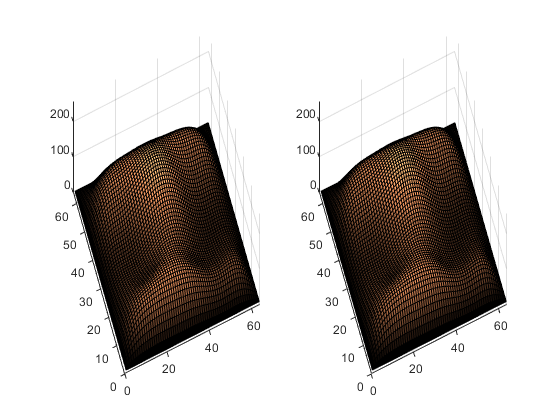

 

pause(3);
for i=1:size(u_euler,1)
    %plot euler
    subplot(1,2,1);
    plot = u_euler(i,:,:);
    plot = squeeze(plot);
    surf(plot);
    colormap copper;
    view([-21 65])
    set(gca,'ZLim',[0 255])
    %plot trapez
    subplot(1,2,2);
    plot = u_trapez(i,:,:);
    plot = squeeze(plot);
    surf(plot);
    colormap copper;
    view([-21 65])
    set(gca,'ZLim',[0 255])
    pause(0.3);
end